# Week5 exercise

Regression, correlation and their statistical significance

% safety first
close all
clear all
clc

% Read in the data
% time range 1950-2020
tr=[1950 2020];
data=xlsread('Boston_Seattle_Sacramento_Atlanta.xlsx','Boston');
data(data==-999)=NaN;
x0=data(:,1); % year
tind=(x0>=tr(1)) & (x0<=tr(2));
year=data(tind,1); % time
jan1=data(tind,2); % January
sep1=data(tind,10); % September

% calculate 95% CI of January temperature trend
% covariance for January
gd=(~isnan(jan1)); % check if missing data
N=length(year);
df=N-2;
c=cov(year(gd),jan1(gd));
a1=c(1,2)/c(1,1);
b1=mean(jan1(gd))-a1*mean(year(gd));
MSE=sum((jan1(gd)-(a1*year(gd)+b1)).^2)/(N-2);
SE2=MSE/sum((year(gd)-mean(year(gd))).^2);
SE=sqrt(SE2);
disp(['SE of the linear trend is ',num2str(SE,2)]);

SE of the linear trend is 0.024


disp(['Linear trend of January is ',num2str(a1,2),' (+/-) ',num2str(2*SE,2),' degF/y']);

Linear trend of January is 0.018 (+/-) 0.048 degF/y


% Matrix for September
gd=(~isnan(sep1)); % check if missing data
N=length(year);
df=N-2;
A=ones(N,2);
A(:,1)=year(gd);
xvec=A\sep1(gd);
a2=xvec(1);
b2=xvec(2);
MSE=sum((sep1(gd)-(a2*year(gd)+b2)).^2)/(N-2);
SE2=MSE/sum((year(gd)-mean(year(gd))).^2);
SE=sqrt(SE2);
disp(['SE of the linear trend is ',num2str(SE,2)]);

SE of the linear trend is 0.011


disp(['Linear trend of January is ',num2str(a2,2),' (+/-) ',num2str(2*SE,2),' degF/y']);

Linear trend of January is 0.039 (+/-) 0.023 degF/y


**January trend is NOT statistically significant because 95% CI covers zero. However Septermber trend is statistically significant. Its 95% CI is always positive.**

Let's look at their time series

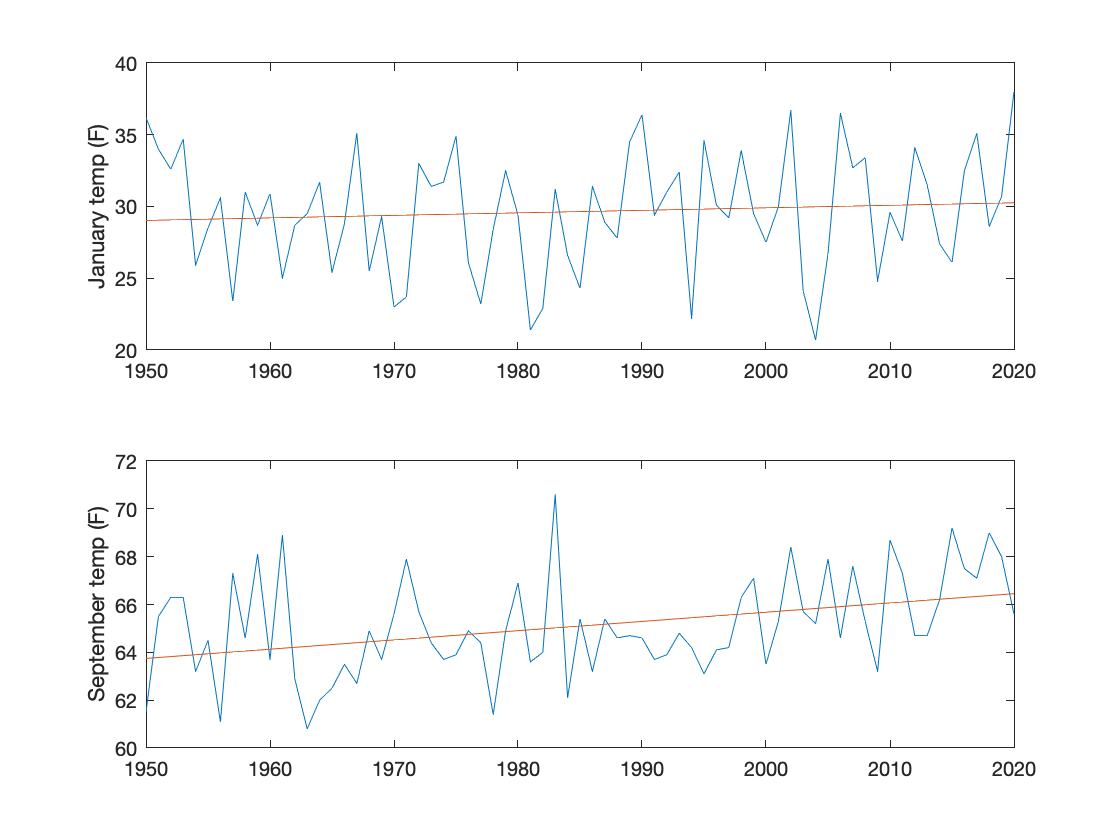

subplot(2,1,1);
plot(year,jan1); hold on;
plot(year,a1*year+b1);
ylabel('January temp (F)')
subplot(2,1,2);
plot(year,sep1); hold on;
plot(year,a2*year+b2);
ylabel('September temp (F)');

### Determine the statistical significance of the correlation of temperatures between different US cities.

df1=xlsread('Boston_Seattle_Sacramento_Atlanta.xlsx','Boston');
df2=xlsread('Boston_Seattle_Sacramento_Atlanta.xlsx','Seattle');
df3=xlsread('Boston_Seattle_Sacramento_Atlanta.xlsx','Sacramento');
df4=xlsread('Boston_Seattle_Sacramento_Atlanta.xlsx','Atlanta');

% pick a month
mon=1; % January
year=df1(:,1);
N=length(year);
Temp=zeros(N,4); % prepare an empty array

% 4 cities
city={'BOS','SEA','SAC','ATL'};
Temp(:,1)=df1(:,mon+1);
Temp(:,2)=df2(:,mon+1);
Temp(:,3)=df3(:,mon+1);
Temp(:,4)=df4(:,mon+1);
Temp(Temp==-999)=NaN;

% select a period
tr=[1900 2020];
gd=(year>=tr(1)) & (year<=tr(2));
D=Temp(gd,:);
c=corrcoef(D,'rows','complete')

c =     1.0000   -0.2315   -0.1276    0.6097
   -0.2315    1.0000    0.5471   -0.4064
   -0.1276    0.5471    1.0000   -0.2106
    0.6097   -0.4064   -0.2106    1.0000


% Let's perform significance test with 95% confidence level (2 tail)
tval = abs(c).*sqrt((N-2)./(1-c.^2));
% since N > 30, we can use Gaussian distribution
tcrit= 2.0;
test = (tval) > tcrit

test = 4×4 logical array
   1   1   0   1
   1   1   1   1
   0   1   1   1
   1   1   1   1


**During winter-months, the temperature of east and west coast cities are negatively correlated: PNA (Pacific North American teleconnection pattern)**

For more information, see [NOAA website](https://www.cpc.ncep.noaa.gov/data/teledoc/pna.shtml)